## **Part 3: Effects of potassium conductance on the neuron**

**Abstract**

For my experiment, I decided to analyze how varying levels of maximum K conductance affect the neuron's ability to make action potentials, using an injected current of 100 pA over the span of 150 ms for each trial. The effects I measured were the neuron's spike count and the peak voltage of its action potentials. After running 6 trials in which I increased G_K_max in 1000 microsiemen intervals from 0-5,000 microsiemens, I found that it generally had an inhibitory effect on the neuron. When there was no conductance, the neuron was unable to hyperpolarize after sodium entered the cell. Higher conductances produced less action potentials. When the maximum K conductance was at 4000 and 5000 microsiemens, no action potentials were produced. Additionally, the action potentials peaked at lower heights with higher conductances, with the exception of the cases where a full action potential was unable to occur.  

**Introduction**

The neuron relies on the dynamics of sodium and potassium to produce action potentials. The maintenance of the imbalance of charges is due to the neuron's selectively permeable membrane, which is embedded with ion-specific channels that open and close. When there are many channels open and enabling the movement of ions between the inside and outside of the cell, it means that the neuron has a high conductance for that ion. The more K channels a neuron possesses, the higher it's maximum K conductance is. Conductance is time and voltage dependent; however in my experiment, I am making the maximum K conductance (represented by the variable 'G_K_max') a fixed value in order to investigate how different conductances affect the frequency with which action potentials occur. 

The default value for G_K_max in a Connor-Stevens model neuron is 2000 microsiemens. I predict that a lower K conductance will make the neuron more excitable because the retention of more potassium in the cell will contribute to the cell's internal positive charge. This will make it easier for the cell to depolarize and achieve a higher maximum voltage. Conversely, I think that a higher K conductance will lead to a more inhibited neuron that produces less action potentials. Because the outward flow of K ions has a hyperpolarizing effect, an increased amount of potassium leaving the cell will make it more negative and it will be harder to produce action potentials. 

I conducted a trial where I set G_K_max equal to 0 to see how many action potentials would occur if there was no potassium conductance. This trial served as the control condition.  

%Conductances     
    G_K_max= 0; %uS %Control condition: K conductance is 0 uS
    G_leak= 30; %ns 
    G_Na_max= 12000; %uS
    G_A_max=4770;
%Reversal potentials
    E_Na= 55; %mV
    E_K= -72; %mV
    E_A= -75; %mV
    E_leak= -17; %mV
%Membrane capacitance
    C= 100; %pF
%Initializing time vector 
    dt= 0.01; %ms
    time= 0:dt:150;
%Initializing membrane voltage vector
    Vm = zeros(size(time));
    Vm(1)= E_leak;
%Allocating vectors for gating variables
    m = zeros(size(time));
    n = zeros(size(time));
    h = zeros(size(time));
    a = zeros(size(time));
    b = zeros(size(time));
%Applied current vector + assignment (I picked 100 pA)
    I_app = zeros(size(time));
    I_app(time > 0) = 100; %pA
%for loop to stimulate neuron
for i = 1:length(time)-1
%voltage dependent gating variables
    alpha_m = (0.38 .* (Vm(i)+29.7)) ./ (1 - exp(-0.1 .* (Vm(i) + 29.7)));
    beta_m = 15.2 * exp(-0.0556 .* (Vm(i) + 54.7));
    alpha_h = 0.266 .* exp(-0.05 .* (Vm(i) + 48)); 
    beta_h = 3.8 ./ (1 + exp(-0.1 .* (Vm(i) + 18)));
    alpha_n = (0.02 .* (Vm(i)+45.7)) ./ (1 - exp(-0.1 .* (Vm(i) + 45.7)));
    beta_n = 0.25 * exp(-0.0125 .* (Vm(i) + 55.7));
    a_infinity = ((0.0761 .* exp(0.0314 .* (Vm(i) + 94.22))) ./ (1 + exp(0.0346 .* (Vm(i) + 1.17)))^(1/3));
    tau_a = 0.3632 + (1.158 ./ (1 + exp(0.0497 .* (Vm(i) + 55.96))));
    b_infinity = (1 ./ (1 + exp(0.0688 .* (Vm(i) + 53.3))))^4;
    tau_b = (1.24) + (2.678 ./ (1 + exp(0.0624 .* (Vm(i) + 50))));
%steady state gating variables (for initialization purposes)
    m_inf = alpha_m ./ (alpha_m + beta_m);
    h_inf = alpha_h ./ (alpha_h + beta_h);
    n_inf = alpha_n ./ (alpha_n + beta_n);
    a_inf = a_infinity;
    b_inf = b_infinity;
            if i==1
                m(1) = m_inf;
                n(1) = n_inf;
                h(1) = h_inf;
                a(1) = a_inf;
                b(1) = b_inf;
            end
%Differential equations 
    dm = (alpha_m * (1 - m(i)) - beta_m * m(i))*dt;
    m(i+1) = m(i) + dm;
    dn = (alpha_n * (1 - n(i)) - beta_n * n(i))*dt;
    n(i+1) = n(i) + dn;
    dh = (alpha_h * (1 - h(i)) - beta_h * h(i))*dt;
    h(i+1) = h(i) + dh;
    da = ((a_infinity - a(i)) ./ tau_a)*dt; 
    a(i+1) = a(i) + da;
    db = ((b_infinity - b(i)) ./ tau_b)*dt;
    b(i+1) = b(i) + db;
%Sub-components of Connor-Stevens model (makes debugging easier)
    I_leak= G_leak * (E_leak - Vm(i));
    I_Na= G_Na_max * (m(i) * m(i) * m(i)) * h(i) * (E_Na - Vm(i));
    I_K= G_K_max * (n(i) * n(i) * n(i) * n(i)) * (E_K - Vm(i));
    I_A= G_A_max * (a(i) * a(i) * a(i)) * b(i) * (E_A - Vm(i));
%The Connor-Stevens model
    dV = ((I_leak + I_Na + I_K + I_A + I_app(i)) / C) * dt;
    Vm(i+1) = Vm(i) + dV;
end

%%%Counting how many spikes were produced when G_K_max=0%%%
%Initializing vector to count spikes
    spikes = zeros(size(time));
%Setting a threshold voltage; if membrane voltage rises to threshold, 
%peaks, and then falls, the maximum value will be recorded as a
%1 in the spike-counter vector
overthreshV = Vm;
overthreshV(Vm < -50) = -50;
    for i = 2:length(time)-1
        if (overthreshV(i) > overthreshV(i-1)) && (overthreshV(i) > overthreshV(i+1))
        spikes(i) = 1;
        end
    end

**Note on the A-current **

It's necessary to address the fact that the neuron has 2 potassium channels (the 2nd one is the A-type channel). Potassium movement is still occurring via A-type channels. A-type channels have activation and deactivation gating variables, represented by a and b. The state of K-channels can be represented by n, the activation of n-gates. a,b, and n are voltage-dependent variables. By using voltage clamps to establish a clear sense of the occurence of the stimulus (lower voltage at 0-4 ms), crossing over the threshold into depolarization (higher voltage at 4-8 ms), and hyperpolarization (lower voltage at 8-12 ms), we can see how these variables behave throughout the course of an action potential. I kept all the default parameters the same and plotted my results. 

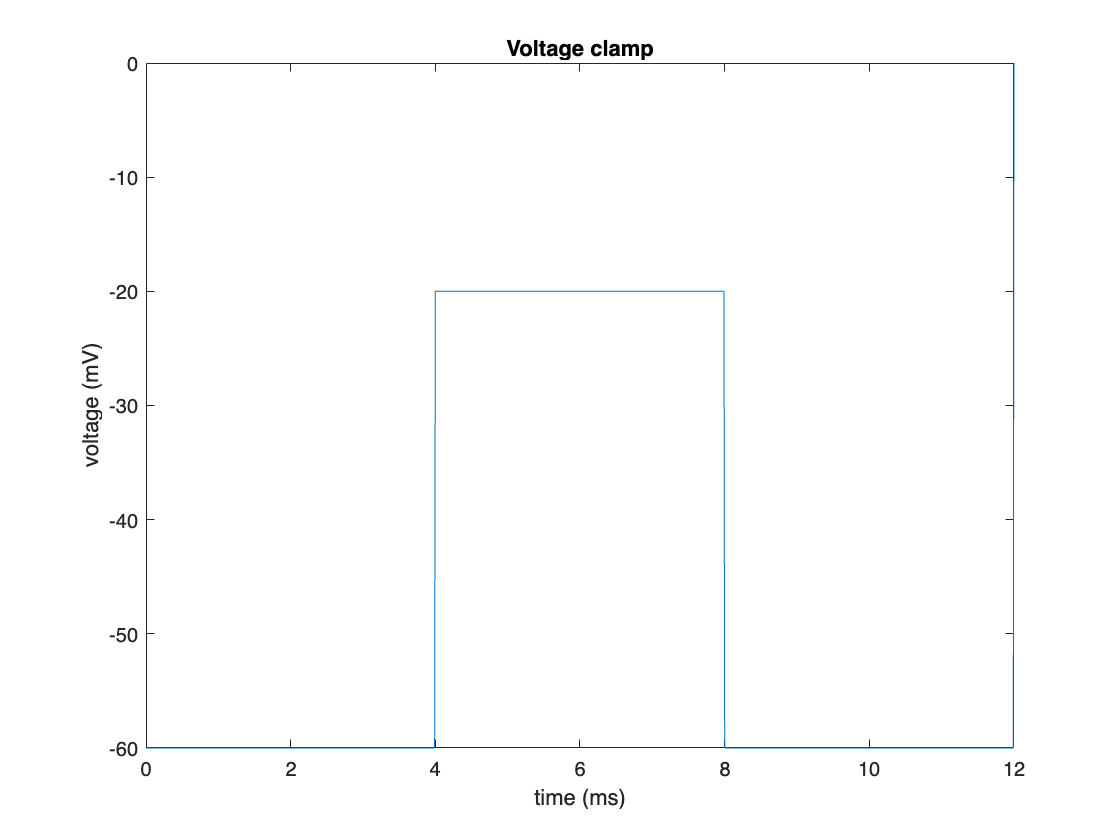

%Voltage clamp experiment to analyze a,b, and n
%Time vector
    dt=0.01;
    Time=0:dt:12;
%Voltage clamp
    voltage= zeros(size(Time));
    voltage(Time <= 4) = -60;
    voltage(Time >= 4 & Time < 8) = -20;
    voltage(Time >= 8 & Time < 12) = -60;
%Making and initializing vectors for gating variables
    a=zeros(size(Time));
    b=zeros(size(Time));
    n=zeros(size(Time));
    a(1)=0;
    b(1)=0;
    n(1)=0;
%Voltage-dependent variables 
    a_infinity = ((0.0761 .* exp(0.0314 .* (voltage + 94.22))) ./ (1 + exp(0.0346 .* (voltage + 1.17))).^(1/3));
    tau_a = 0.3632 + (1.158 ./ (1 + exp(0.0497 .* (voltage + 55.96))));
    b_infinity = (1 ./ (1 + exp(0.0688 .* (voltage + 53.3)))).^4;
    tau_b = (1.24) + (2.678 ./ (1 + exp(0.0624 .* (voltage + 50))));
    alpha_n = (0.02 .* (voltage+45.7)) ./ (1 - exp(-0.1 .* (voltage + 45.7)));
    beta_n = 0.25 * exp(-0.0125 .* (voltage + 55.7));
%Solving differential equations using for loops to fill vectors with values
    for i = 2:length(Time)
        dn = ((alpha_n(i) * (1 - n(i-1))) - (beta_n(i) * n(i-1))) * dt;
        n(i) = n(i-1) + dn;
    end
    for i = 2:length(Time)
        da = ((a_infinity - a(i-1)) ./ tau_a)*dt; 
        a(i) = a(i-1) + da(i);
    end
    for i = 2:length(Time)
        db = ((b_infinity - b(i-1)) ./ tau_b)*dt;
        b(i) = b(i-1) + db(i);
    end
%Plotting voltage clamp
figure
plot(Time,voltage)
xlabel('time (ms)')
ylabel('voltage (mV)')
title('Voltage clamp')

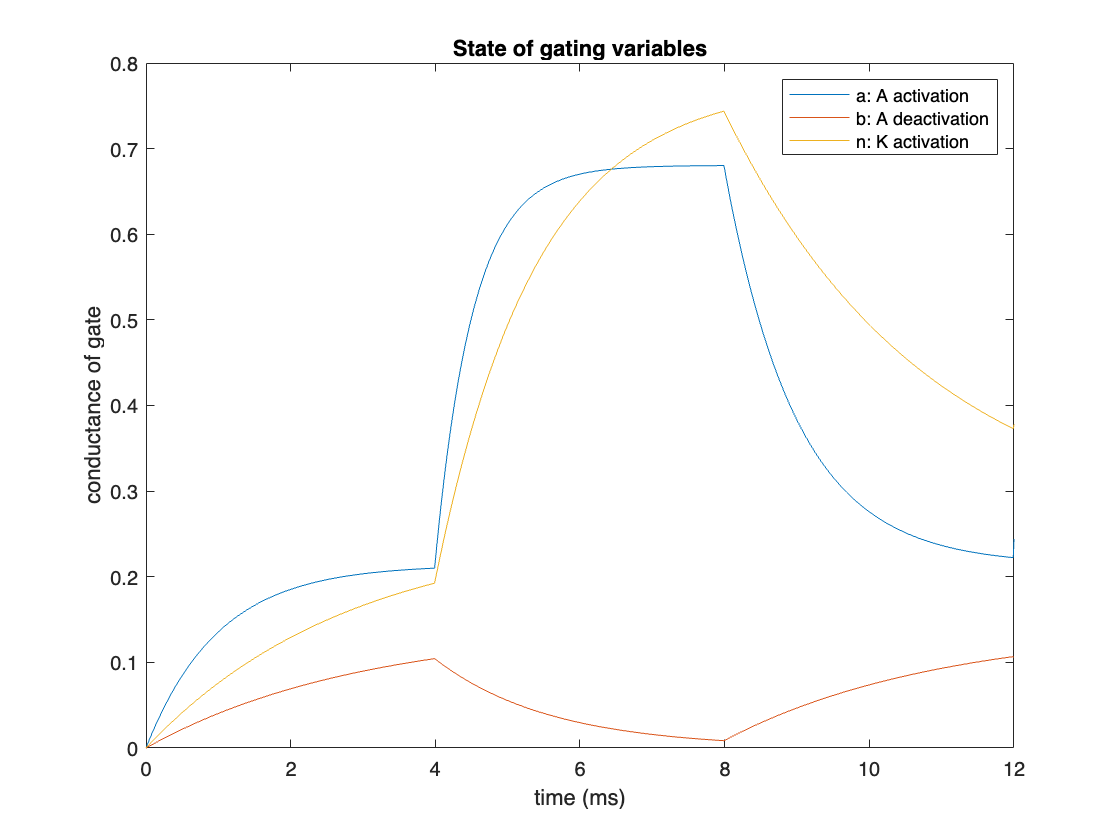

%Plotting states of gating variables
plot(Time,a)
hold on
plot(Time,b)
hold on
plot(Time,n)
xlim([0 12])
legend('a: A activation','b: A deactivation','n: K activation')
xlabel('time (ms)')
ylabel('conductance of gate')
title('State of gating variables')

The K current is the most active at the peak of the action potential, which is when the neuron is very depolarized and contains a lot of sodium. The K current has a much larger effect on the membrane voltage because it leaves the cell at a time where the cell is very positive, thus the difference between the intracellular and extracellular charges is more drastic. You can also see on the graph that the yellow line, which represents the proportion of activated n-gates, is higher than the other lines after the peak of the action potential. For my experiment, the potassium channel I want to focus on is the K-channel. The conductance of the A-current is kept the same throughout the trials, so that the effects of changes in potassium levels can only be attributed to K's conductance. 

**Results of the control trial**

%Counting the # of times 1 appears in the spikes vector
totalspikes = sum(spikes)

totalspikes = 1

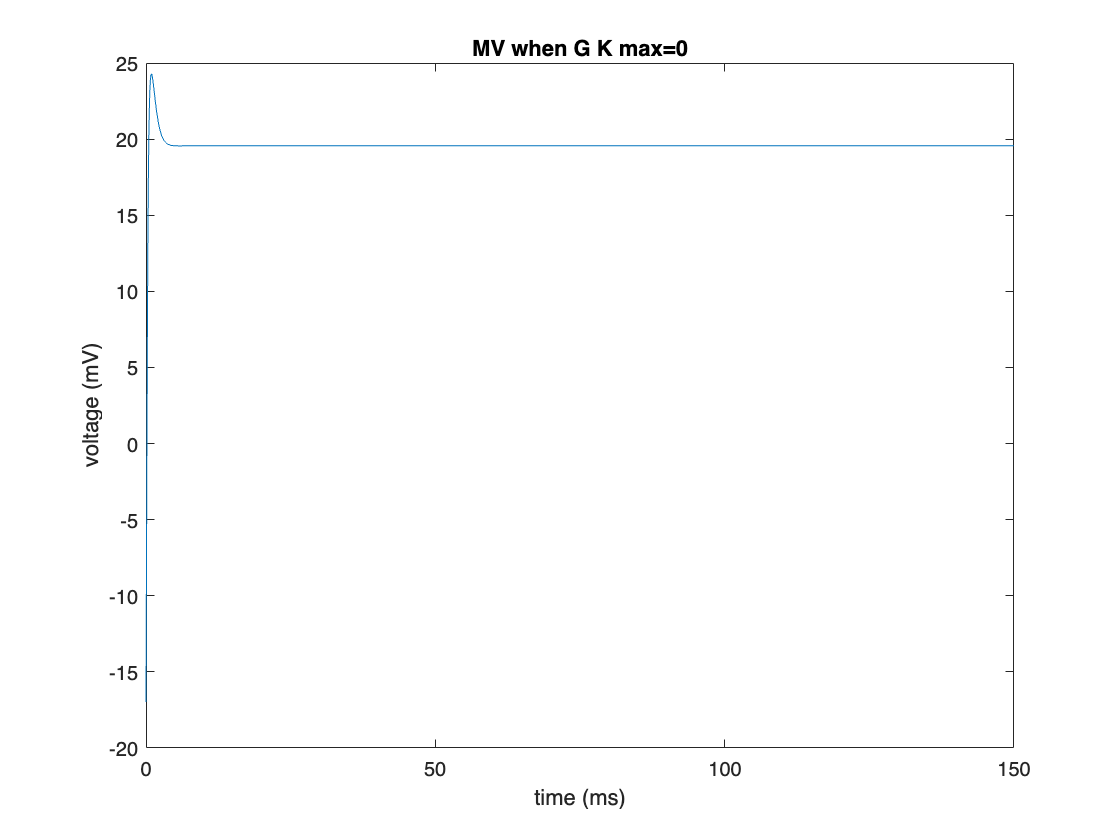

%Plotting the spike, so its easier to visualize
figure
plot(time,Vm)
xlabel('time (ms)')
ylabel('voltage (mV)')
title('MV when G K max=0')

Setting the conductance equal to 0 produced 1 spike. However upon inspection of the graph, you can see that there is a spike but **there were 0 action potentials**. An action potential is unable to be produced without the outward flow of K ions. At time=0 ms, a current of 100 pA is injected, stimulating the neuron to open its sodium channels. The inward rush of sodium depolarizes the cell and causes the membrane voltage to rise from -17 to almost 25 mV. At the peak, the inside of the cell is very positively charged. In a normal action potential, this is when K channels would open and allow for potassium to flow out. Since there is zero conductance, that means that the K channels remain closed at this point. The momentum built up by sodium is lost, and the membrane voltage settles slightly below the peak at about 20 mV. 

The cell does not return to its original resting membrane potential of -17 mV. This is because the inability of positively charged potassium to leave the cell makes the cell more positive overall, which is why it evens out at a much higher voltage.  

**Trials **

My first trial will have a K conductance of 1000 uS. The second trial will have a K conductance of 2000 uS, which is the default parameter as defined by the Connor-Stevens model. The third trial will test 3000 uS, the fourth trial will test 4000 uS, and the fifth trial will test 5000 uS. For convenience, I condensed the code above into a single function that will calculate the number of spikes given an inputted G_K_max conductance. I also made a function that will plot its corresponding graph. This function also sets the maximum K conductance equal to the input. 

calculatenumberofspikes_K(1000)

There are 26 spikes when G_K_max= 1000


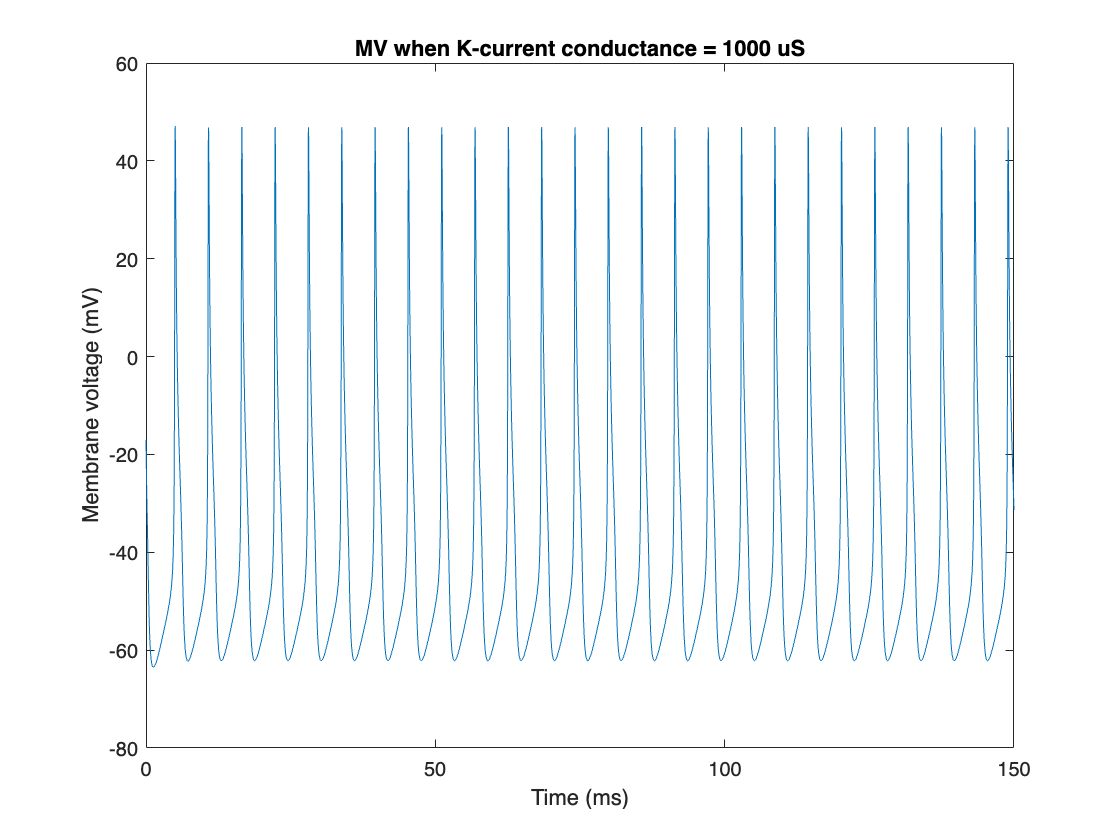

graphofvoltage_K(1000)

calculatenumberofspikes_K(2000)  

There are 23 spikes when G_K_max= 2000


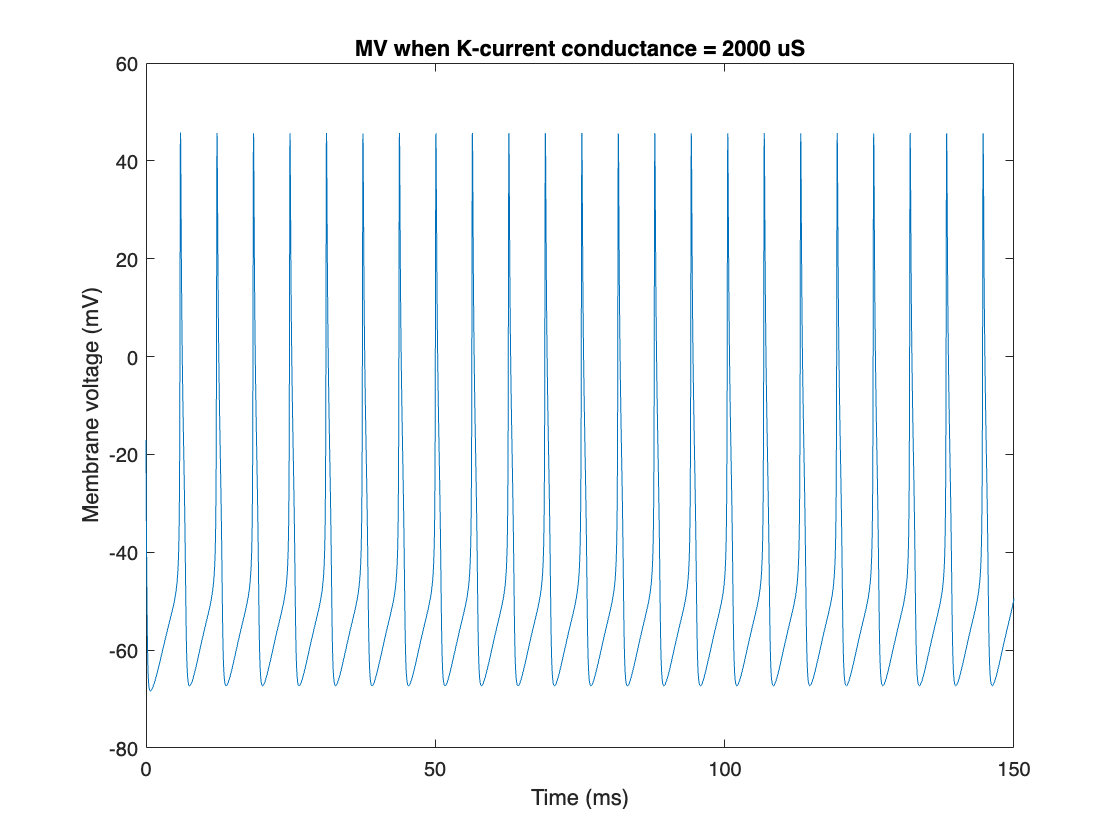

graphofvoltage_K(2000)

calculatenumberofspikes_K(3000)

There are 20 spikes when G_K_max= 3000


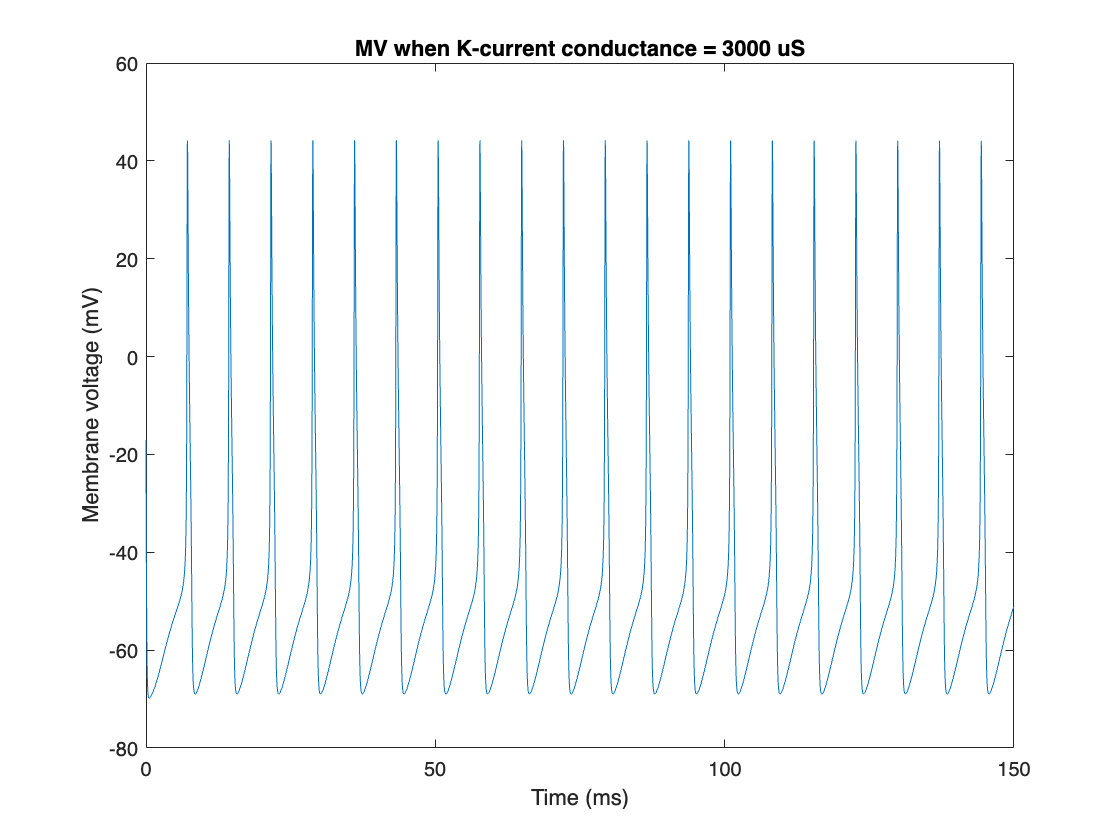

graphofvoltage_K(3000)

calculatenumberofspikes_K(4000)

There are 0 spikes when G_K_max= 4000


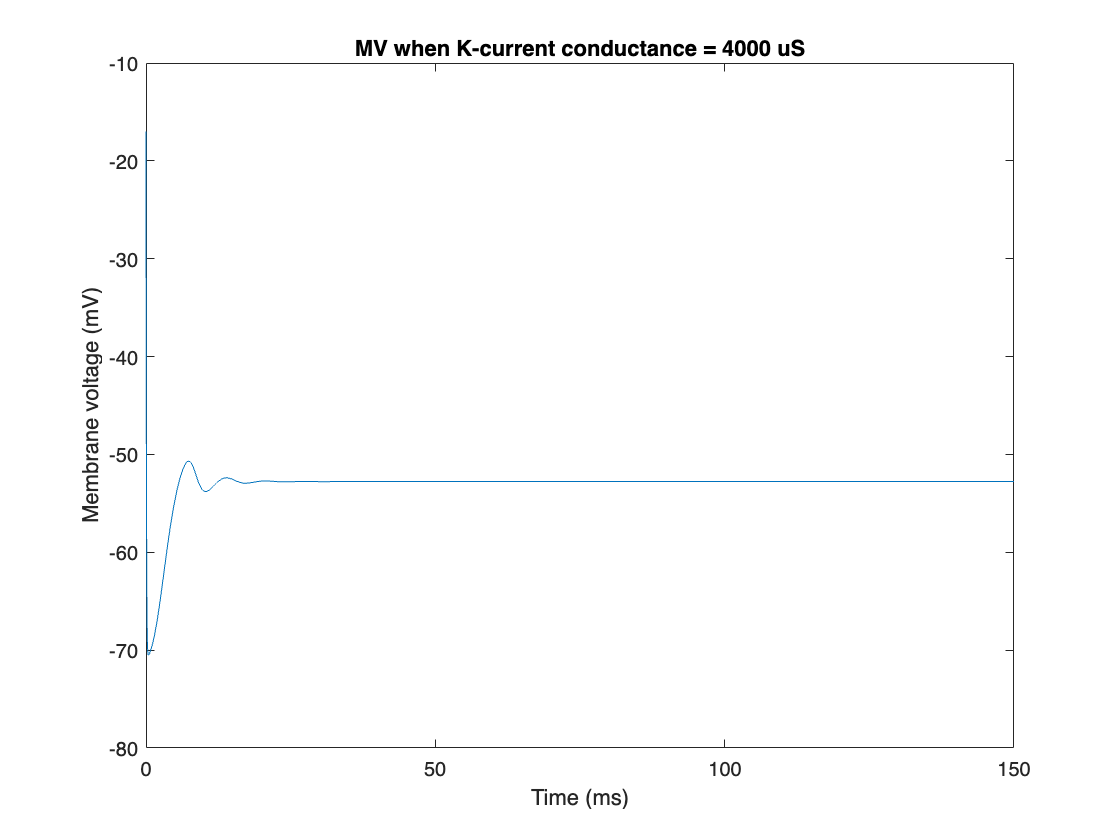

graphofvoltage_K(4000)

calculatenumberofspikes_K(5000)

There are 0 spikes when G_K_max= 5000


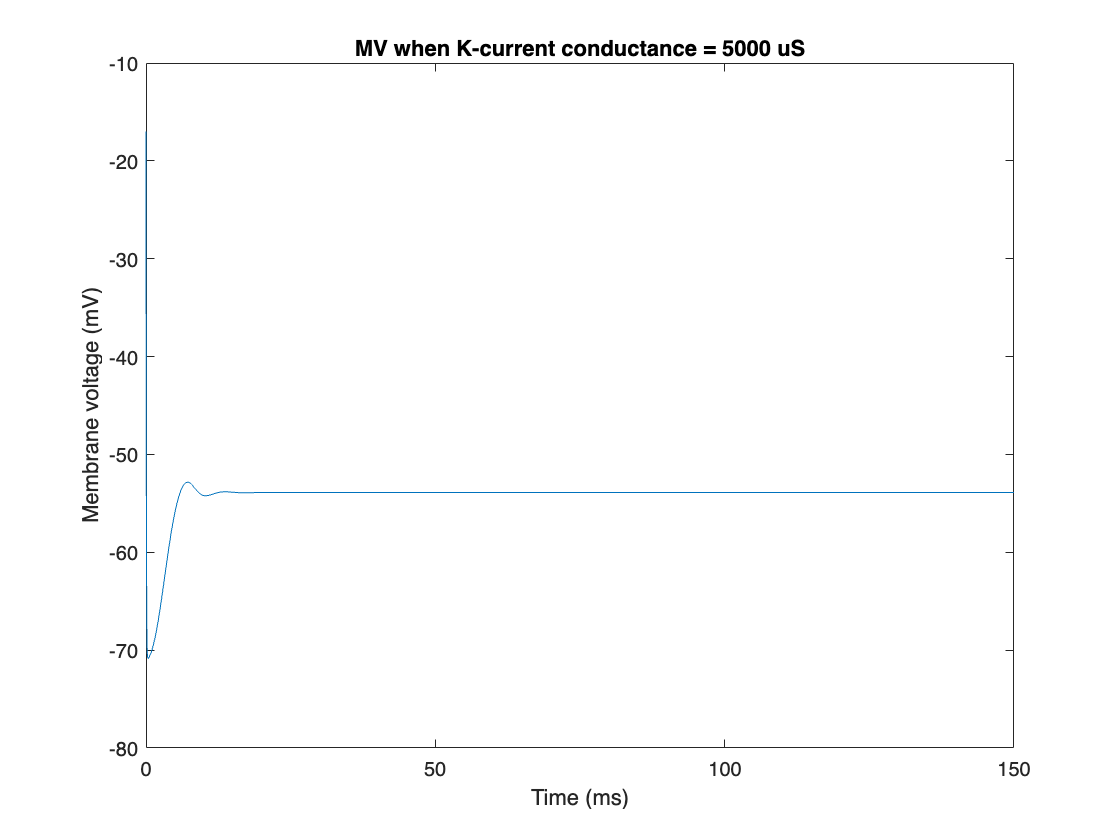

graphofvoltage_K(5000)

**Results**

The first trial resulted in 26 action potentials. The second trial had 23 action potentials. The number of action potentials continued to decrease, with the third trial yielding 20 action potentials. I made a function that sets G_K_max equal to the user's input and finds the peak of the action potentials it produces. 

findpeakofspike_K(1000)

The spike peaks at 51.0225 mV when G_K_max= 1000


findpeakofspike_K(2000)

The spike peaks at 49.8255 mV when G_K_max= 2000


findpeakofspike_K(3000)

The spike peaks at 48.2271 mV when G_K_max= 3000


The maximum voltage decreases steadily as K conductance increases. Earlier, I hypothesized that increasing K conductance would inhibit the neuron's firing rate and spike magnitude and I was correct. This is because the neuron is harder to excite. 

When conductance was set to 4000 and 5000 in trials 4 and 5, no action potentials occurred. Somewhere between 3000 and 4000 microsiemens, the inhibitory effects became strong enough to prevent the neuron from reaching the threshold voltage needed to produce an action potential. The "all-or-nothing" nature that makes the action potential so dynamic is demonstrated here. When G_K_max=4000, it looks like the injected current stimulated the neuron a little bit. The stimulus induced a small boost in the membrane voltage and minor oscillations before settling into a steady state. The same thing happened when G_K_max=5000, except the magnitude of the oscillations were even smaller. 

My results are summarized here in a table: 

Trial = ["Control";1;2;3;4;5];
G_K_Max = ["0 microsiemens";"1000 microsiemens";"2000 microsiemens";"3000 microsiemens";"4000 microsiemens";"5000 microsiemens"];
ActionPotentials = [0;26;23;20;0;0];
MaxVoltageofAP = ["NA";"51.02 mV";"49.83 mV";"48.23 mV";"NA";"NA"];
results = table(Trial,G_K_Max,ActionPotentials,MaxVoltageofAP)

results = 6×4 table
      Trial            G_K_Max          ActionPotentials    MaxVoltageofAP
    _________    ___________________    ________________    ______________

    "Control"    "0 microsiemens"               0             "NA"        
    "1"          "1000 microsiemens"           26             "51.02 mV"  
    "2"          "2000 microsiemens"           23             "49.83 mV"  
    "3"          "3000 microsiemens"           20             "48.23 mV"  
    "4"          "4000 microsiemens"            0             "NA"        
    "5"          "5000 microsiemens"            0             "NA"        


**Conclusion**

For my experiment, I decided to systematically alter the conductance of potassium and study its inhibitory effects on the frequency and magnitude of the neuron's action potentials. During the control trial when there weren't any open K channels, there were no action potentials produced. This was because after the cell depolarized, it was unable to hyperpolarize, resulting in an incomplete action potential. In trials 1,2, and 3, the number of action potentials decreased from 26 to 23 to 20, as maximum K conductance increased. This happened because it became harder for the neuron to be excited by the applied current; an increased amount of positively charged potassium leaving the cell resulted in a more negatively charged neuron. And finally in trials 4 and 5, high G_K_max's inhibitory effect prevented the applied stimulus from inducing a reaction that was strong enough to pass the threshold voltage and create an action potential.  